ASSIGNMENT

1.(a) Uniform distribution over the interval $\left\lbrack -2\pi ,\pi \right\rbrack$

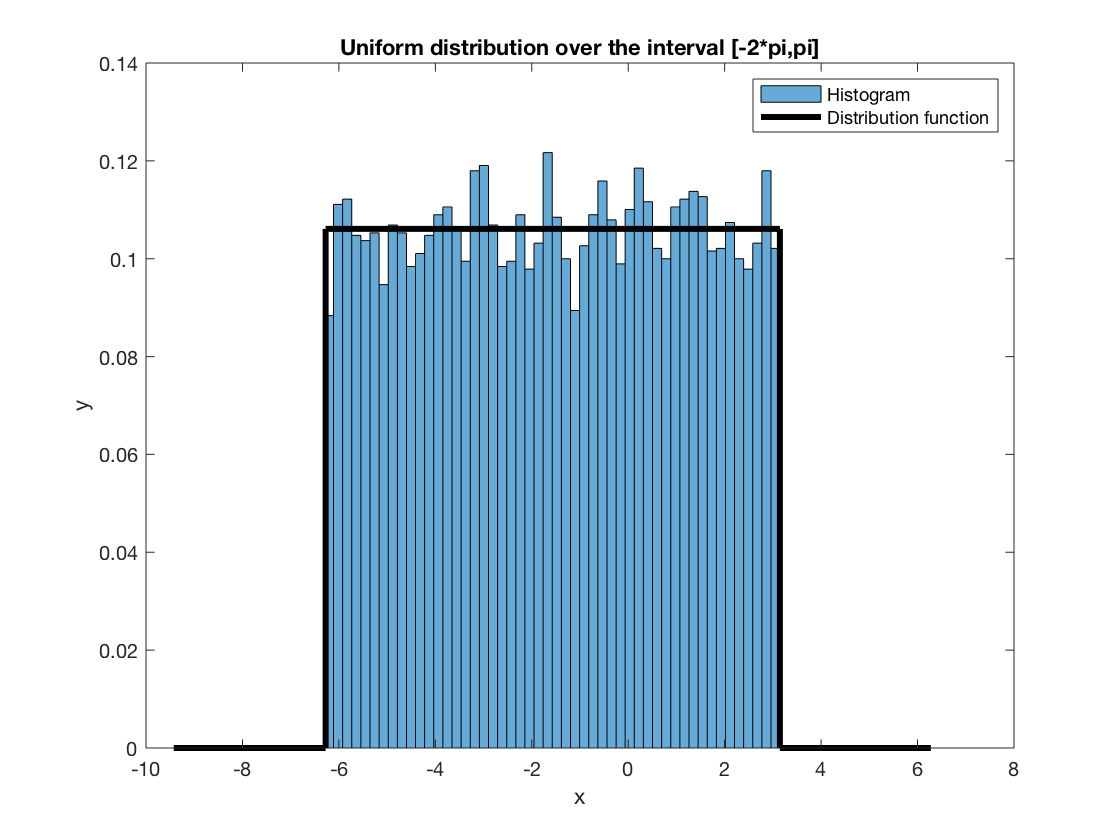

% Call the function 
t = uniform(-2*pi,pi,10000);
%Plot the histogram and normalize values
histogram(t,50,'Normalization',"pdf")

hold on

%Plot the pdf 
x = -3*pi:0.01:2*pi;
pd = makedist('Uniform','lower',-2*pi,'upper',pi);
f = pdf(pd,x);
stairs(x,f,'k',"LineWidth",3)

title('Uniform distribution over the interval [-2*pi,pi]')
xlabel('x')
ylabel('y')
legend('Histogram','Distribution function')

hold off

(b) Uniform distribution over the union of the three intervals [1, 2] ∪ [3, 4] ∪ [5, 6]	 

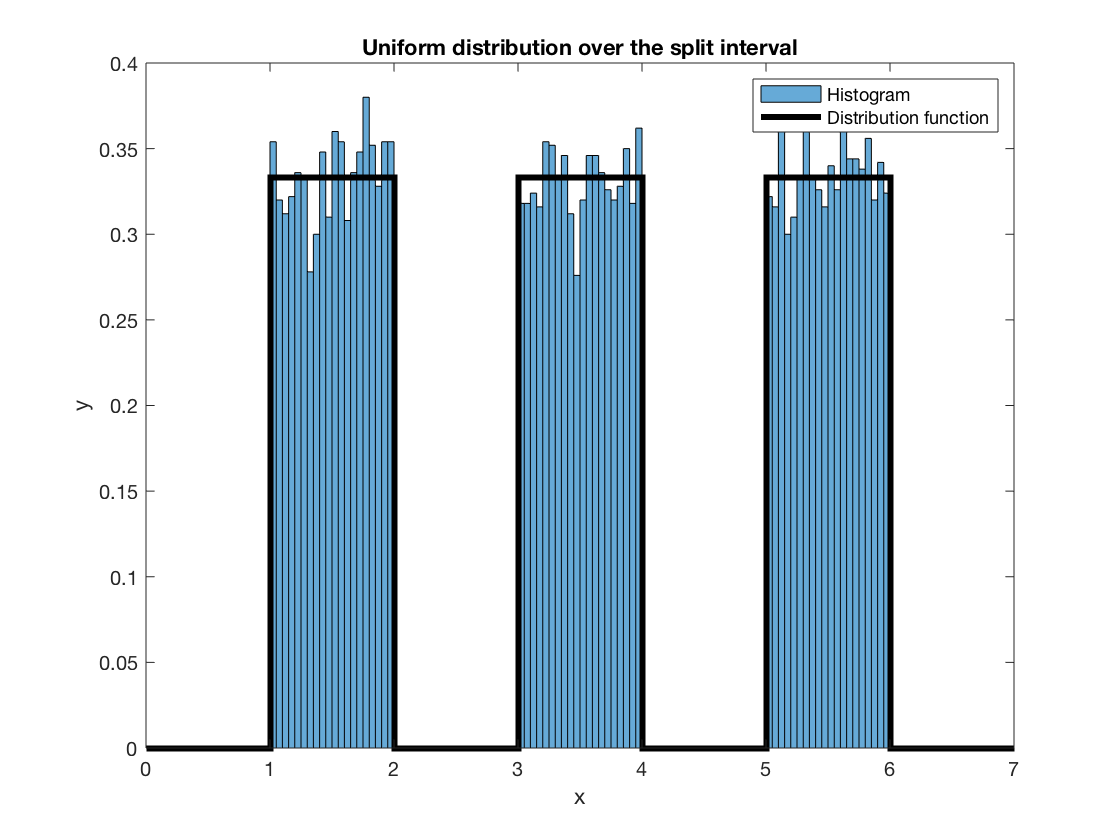

clear 
clc

%Call the function 
t = splituniform(1,2,3,4,5,6,10000);
%Plot the histogram and normalize values
histogram(t,100,'Normalization',"pdf")

hold on 

%Plot the pdf
y = [0 1/3 0 1/3 0 1/3 0 0];
stairs(0:7, y, 'k',"LineWidth",3)

title('Uniform distribution over the split interval')
xlabel('x')
ylabel('y')
legend('Histogram','Distribution function')

hold off

(c) Gaussian distribution with a given mean value 12.5 and standard deviation 3 using the Box-Muller Method

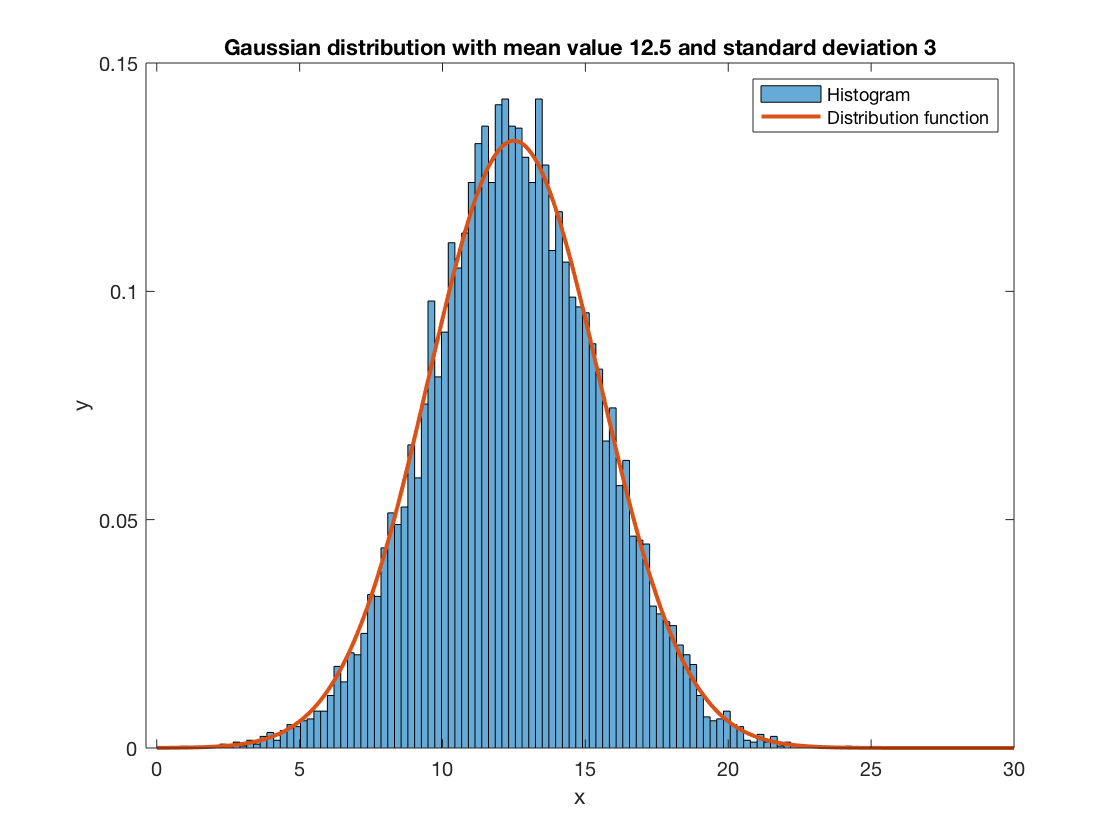

clear
clc

%Call the function 
t = normal(12.5,3,10000);
%Plot the histogram and normalize values
histogram(t,100,"Normalization","pdf")

hold on 

%Plot the pdf
x = 0:0.1:30;
mean = 12.5;
std = 3;
f = exp(-(x-mean).^2./(2*std^2))./(std*sqrt(2*pi));
plot(x,f,'linewidth',2)

title('Gaussian distribution with mean value 12.5 and standard deviation 3')
xlabel('x')
ylabel('y')
legend('Histogram','Distribution function')

hold off

(d) Continuous distribution with probability density function $f\left(x,\lambda \right)=\lambda e^{-\lambda x}$

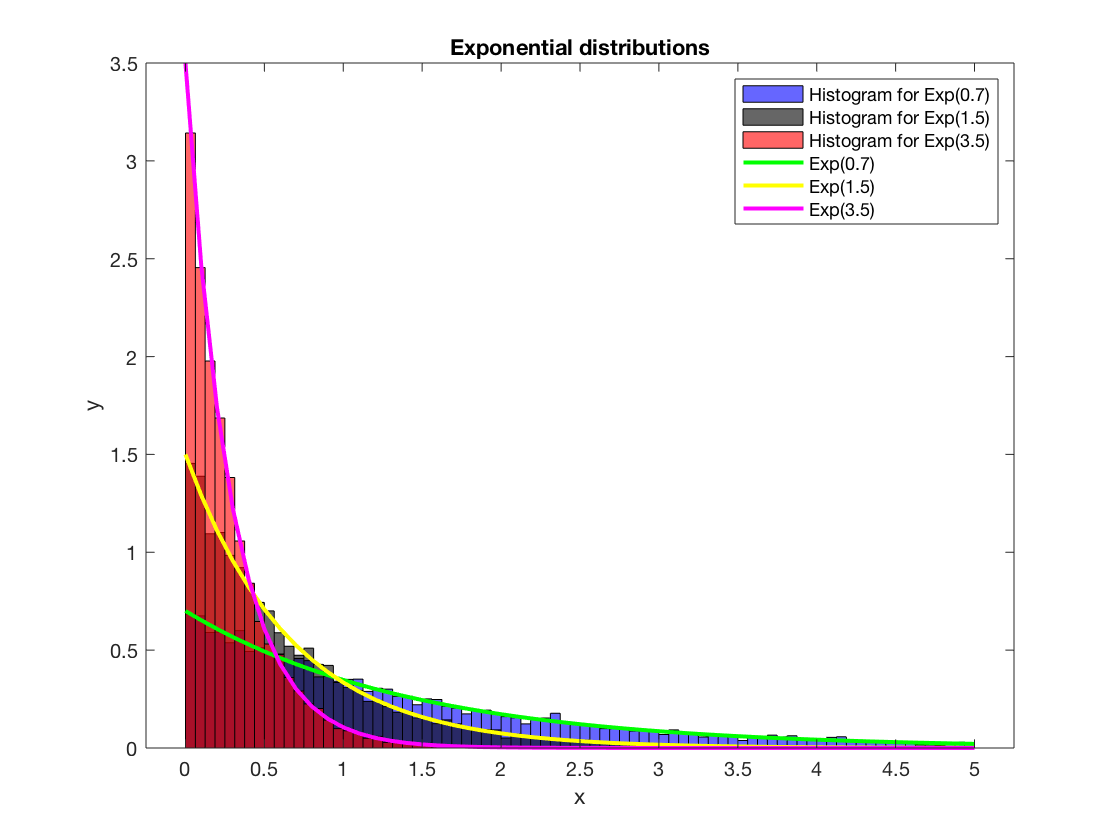

clear 
clc

%Call the function 
t1 = exponential(0.7,10000);
%Plot the histograms and normalize values
histogram(t1,80,"Normalization","pdf","FaceColor",'b',"BinLimits",[0,5])

hold on

%Do the same for the other distributions
t2 = exponential(1.5,10000);
histogram(t2,80,"Normalization","pdf","FaceColor",'k',"BinLimits",[0,5])
t3 = exponential(3.5,10000);
histogram(t3,80,"Normalization","pdf","FaceColor",'r',"BinLimits",[0,5])

%Plot the pdfs
x = 0:0.1:5;
l1 = 0.7;
l2 = 1.5;
l3 = 3.5;
f1 = l1*exp(-l1*x);
f2 = l2*exp(-l2*x);
f3 = l3*exp(-l3*x);
plot(x,f1,'g',x,f2,'y',x,f3,'m',"LineWidth",2)

title('Exponential distributions')
xlabel('x')
ylabel('y')
legend('Histogram for Exp(0.7) ','Histogram for Exp(1.5)', 'Histogram for Exp(3.5)', 'Exp(0.7)','Exp(1.5)','Exp(3.5)')


hold off

(e)

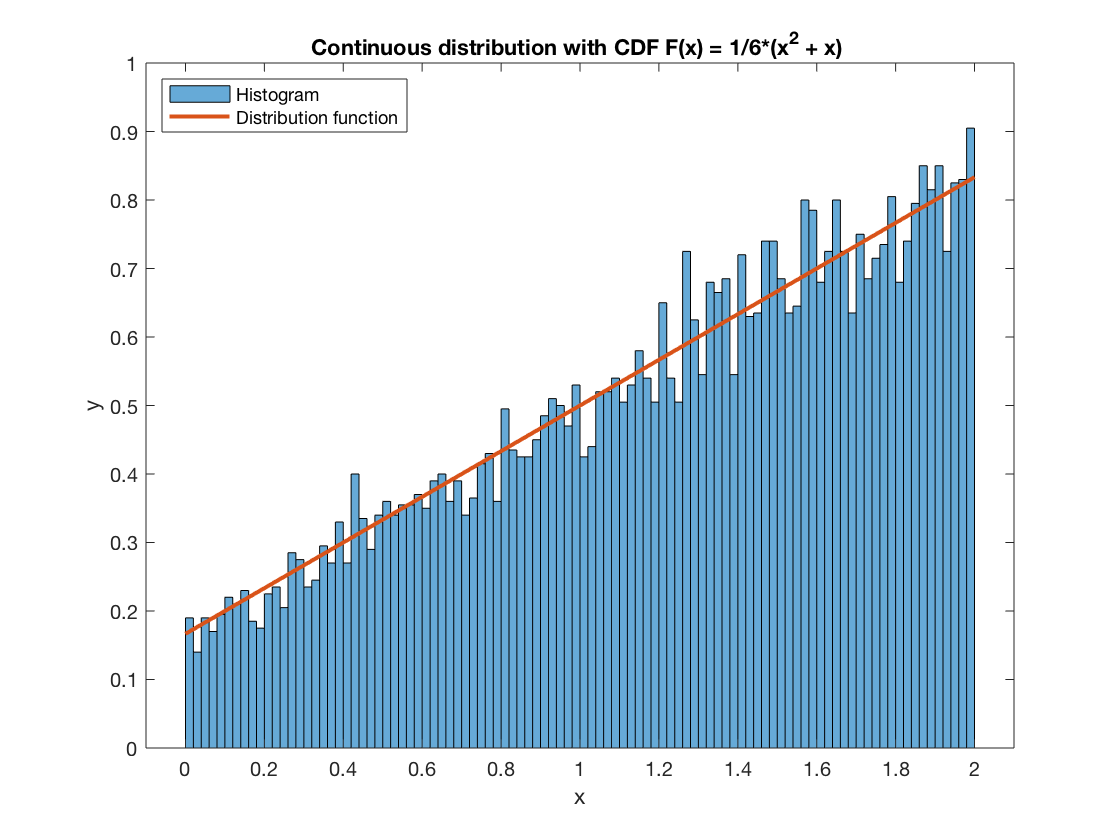

clear
clc

%Call the function 
t = cdf(10000);
%Plot the histogram and normalize values
histogram(t,100,"Normalization","pdf")

hold on 

%Plot the pdf
x = 0:0.01:2;
f = x/3 + 1/6;
plot(x,f,"LineWidth",2)

title('Continuous distribution with CDF F(x) = 1/6*(x^2 + x) ')
xlabel('x')
ylabel('y')
legend('Histogram','Distribution function','Location',"northwest")

hold off

FUNCTIONS

%Uniform distribution over [a,b] with N randomly obtain samples

function y = uniform(a,b,N)

    y = (b-a)*rand(N,1) + a;

end 

% Uniform distribution over the union of [a,b],[c,d] and [e,f] with N N randomly obtain samples
function y = splituniform(a,b,c,d,e,f,N)

    x = rand(N,1);
    
    %Split x into 3 parts
    I1 = x <= 1/3;
    I2 = x>=1/3 & x<=2/3;
    I3 = x>=2/3;
    
    % Values have to be adjust according to which section they belong to
    y = 3*(b-a)*(x.*I1) + a*I1 + 3*(d-c)*(x.*I2 - 1/3*I2) + c*I2 +3*(f-e)*(x.*I3 - 2/3*I3) + e*I3; 
    
end  

% Gaussion distribution with given mean and standard deviation with N
% randomly chosen samples (via Box-Muller Method)
function y = normal(mean,std,N)
    
    x1 = rand(N,1);
    x2 = rand(N,1);
    %Sample r from the Rayleigh Distribution via Inverse Function Method
    r = sqrt(-2*log(1-x1));
    %Sample theta Uniform Distribution over [0,2*pi]
    theta = 2*pi*x2;
    %Standard Normal
    standardnormal = r.*cos(theta); 
    %This step will give us our required distribution
    y = std*standardnormal + mean;

end

%Exponential Distribution with parameter l with N randomly chosen samples
function y = exponential(l,N)
    
    x = rand(N,1);
    y = -log(1-x)/l;

end

%Continuous Distribution with the given CDF
function y = cdf(N)
        
     x = rand(N,1);
     y = (-1 + sqrt(1+24*x))/2;

end